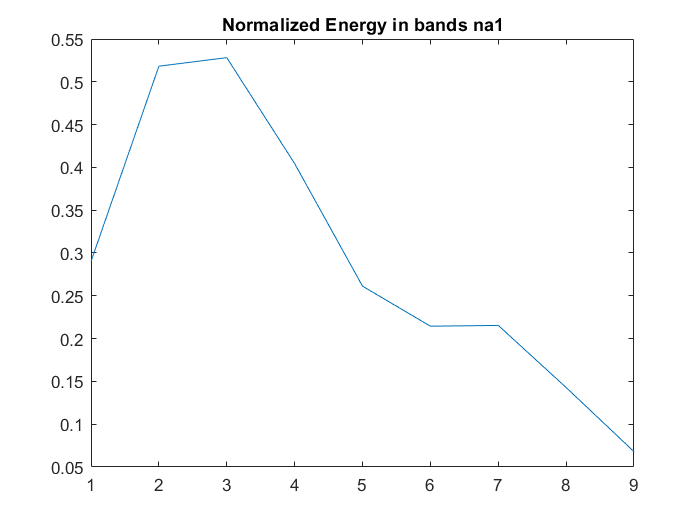

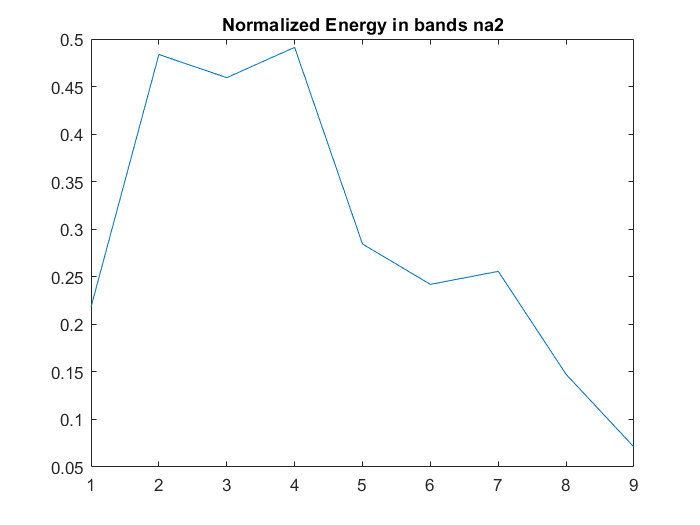

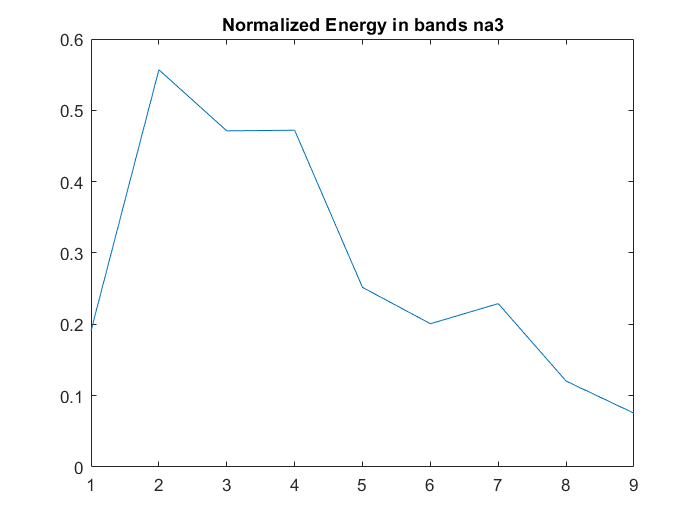

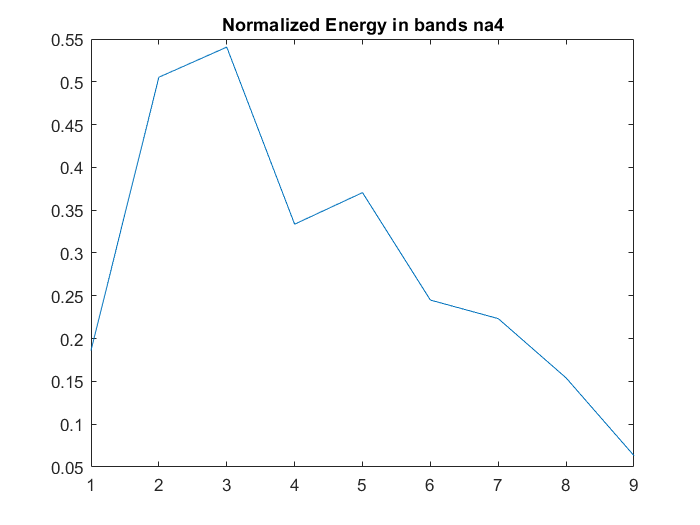

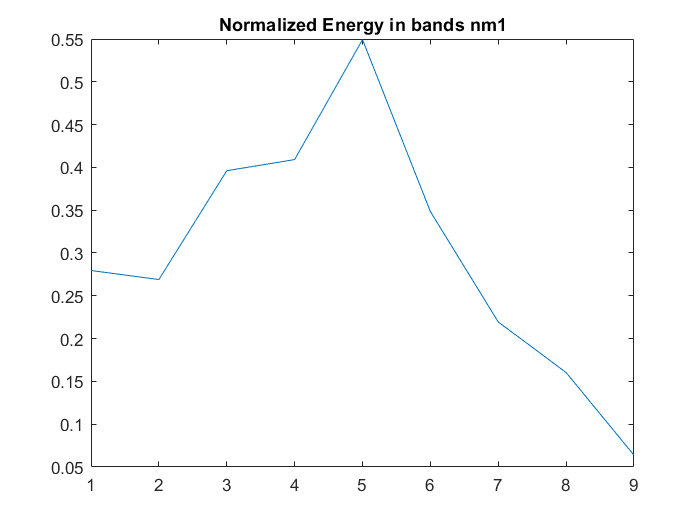

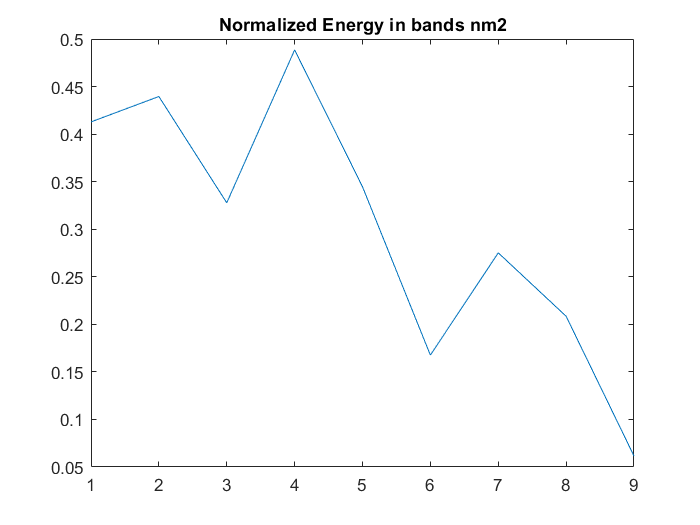

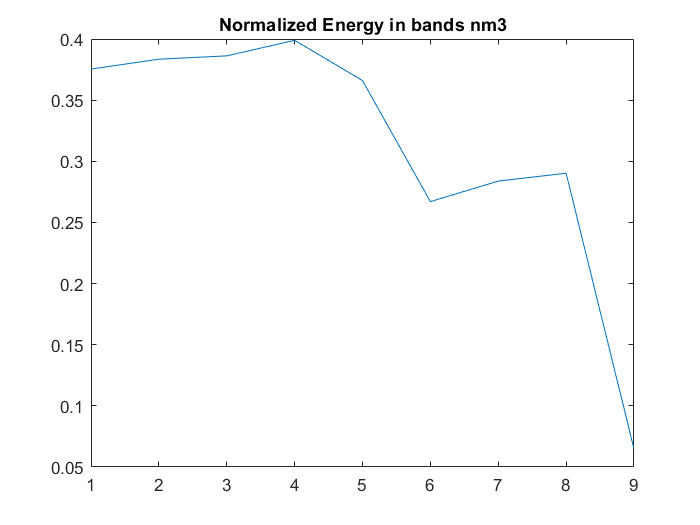

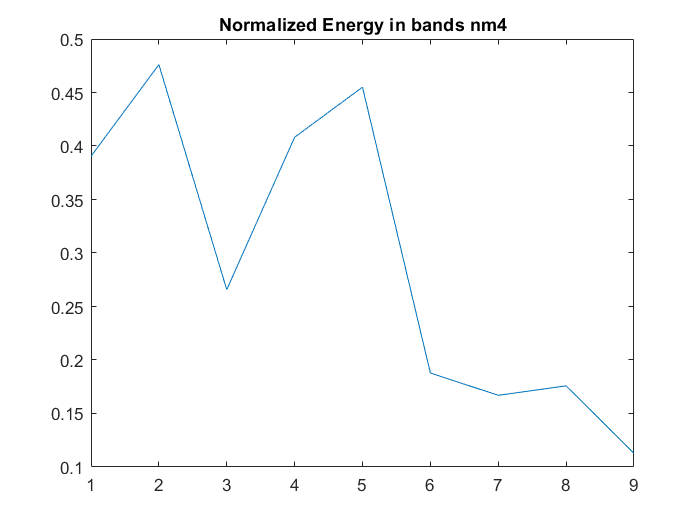

close all;
clear;
numberOfBands = 10;
p = ["n","p","r","s"];
t = ["a","m"];

targetLoudness = -20;

for k = 1:length(p)
    for j = 1:2
        for i=1:4
        filename = "C:\Users\sridh\Documents\MATLAB\DSP\Assignment2\audio\"+ p(k) + t(j) +i+ ".wav";
        [signal,Fs] = getAudio(filename);
        s = preEmphasis(signal);
        [loudness, LRA] = integratedLoudness(s, Fs);
 
        gain = 10^((targetLoudness - loudness)/20);
        s = s.*gain;
        %[loudnessNorm, LRA] = integratedLoudness(signal,Fs)
        
        %plotSignal(s,signal,p(k),t(j),i);
        %fprintf("_______________");
        [filtbank,f,energies] = baapu(s,Fs,numberOfBands);
        energy(k,(j-1)*4+i,:) = energies;
        
        figure("Name", "i = " + i + "t = " + t(j));
        plot(energies(1:end-1));
        title("Normalized Energy in bands " + p(k) + t(j) + i);
       

        end
        
    end

end



    

%energy


%t = (0:(length(signal)-1))/Fs;
%plot(t,signal); xlabel("Time(s)"); ylabel("Amplitude"); title("Audio");

%t = (0:(length(signal)-1))/Fs;
%fsignal = noisefilt(signal,Fs);
%plot(t,fsignal); xlabel("Time(s)"); ylabel("Amplitude"); title("Filtered Audio");
%env2 = hilbert(fsignal);
%plot(abs(env2));

%[yf,yfft] = FFT(signal,length(signal),Fs);
%plot(yf,20*log(abs(yfft)));
%xlabel("Frequency"); ylabel("Amplitude (dB)"); title("Unfilteres FFT");

%env = hilbert(signal);
%plot(abs(env));


%[filtbank,f] = banks(signal,Fs,numberOfBands);

%energies = powers(filtbank,signal)






function [x,Fs] = getAudio(name)
Fs = 6000;  %Sampling ratio given
[audio,fs] = audioread(name);
downratio = floor(fs/Fs);
Fs = fs/downratio;  %Might not be exact required frequency
x = downsample(audio,downratio);
end

function [sos] = genfilter(Fs, f)
    [A, B, C, D] = butter(16,[f(1) f(2)]/(Fs/2));    %%Normalized frequency has to be supplied
    sos = ss2sos(A,B,C,D);    %%Convert state space matrix to something usable 
end


function [filtbank,f] = banks(x,Fs, k)
    f = linspace(0,Fs/2-1,k+1);
    %LPF
    %[A,B,C,D] = butter(8,2*f(1)/Fs);
    %sos=ss2sos(A,B,C,D);
    [b,a] = butter(16,2*f(2)/Fs);
    filtbank(1,:) = filtfilt(b,a,x);
    for i = 2:(length(f)-1)
        g = [f(i),f(i+1)];
        sos = genfilter(Fs,g);
        filtbank(i,:) = filtfilt(sos,1,x);
    end
end

function [y] = noisefilt(x,Fs)
n = 0.15*Fs;
%if shouvik's file, increase this length
nmean = mean(abs(x(1:n)));
for i = 1:(length(x))
    if(abs(x(i))<5*nmean)
        y(i) = 0;
    else
        y(i) = x(i);
    end
end
end

function [f,DFFT] = FFT(xt,N,Fs)
DFFT2 = fft(xt,N)/N;
DFFT = fftshift(DFFT2);
f = Fs/length(DFFT)*linspace(-length(DFFT)/2,length(DFFT)/2-1,N);
end

function [y] = powers(x,xorig)
    dim = size(x);
    for i=1:dim(1)
        y(i) = norm(x(i,:));
    end
    porig = norm(xorig);
    y = y/porig;
    %y = y/sum(y);
end

function [] = frequencydomain(filtbank,Fs,numberOfBands)
for i=1:numberOfBands
    [yf,yfft] = FFT(filtbank(i,:),length(filtbank(i,:)),Fs);
    figure("name","i");
    plot(yf,20*log(abs(yfft)));
    xlabel("Frequency"); ylabel("Amplitude (dB)"); title("Filtered FFT f1 = "+ f(i) + " f2 = "+f(i+1));
    xlim([-4000 4000]);
end
end

function [filtbank,f,energies] = baapu(signal,Fs,numberOfBands)
[filtbank,f] = banks(signal,Fs,numberOfBands);
energies = powers(filtbank,signal);
end

function [y] = preEmphasis(x)
    h = [1 -0.95];
    y = filter(h,1,x);
end

function plotFFT(s,signal,Fs)
    figure("Name","FFT");
    [yf,yfft] = FFT(signal,length(signal),Fs);
    [yff,yfftf] = FFT(s,length(s),Fs);
    subplot(211);
    plot(yf,20*log(abs(yfft)));
    xlabel("Frequency"); ylabel("Amplitude (dB)"); title("UnFiltered FFT");
    subplot(212);
    plot(yff,20*log(abs(yfftf)));
    xlabel("Frequency"); ylabel("Amplitude (dB)"); title("Filtered FFT");
end

function plotSignal(s,signal,p,t,i)
        figure("Name","Time domain Signal" + p + t + i);
        subplot(211);
        plot(signal); title("Time domain unfiltered" + p + t + i);
        subplot(212);
        plot(s); title("Time domain filtered" + p + t + i);
end